**State Space Modeling Tutorial - Part 2, 1D Nonlinear Gaussian Model**

In the first part of this tutorial, we computed filter and smoother estimates for linear and Gaussian state and observation models. We saw that the filter and smoother densities were always themselves Gaussian and the filter could be estimated efficiently with the Kalman filter.

What happens when one or both of the models is nonlinear? In this part of the tutorial we will compare estimates of the filter solution using numerical integration to the extended Kalman filter (EKF), which uses a Gaussian approximation to the filter distribution. 

We start by replacing the linear state model with the nonlinear model, $x_t |x_{t-1} ~N\left(A*\mathrm{atan}\left(x_{t-1} \right),\Sigma_x \right)$. We'll leave the observation model the same. Let's generate data from this model system. 

%% Generate Data
% State model: x(t) = A*atan(x(t-1)) + Sigx * N(0,1)
% Observation model: y(t) = H*x(t) + Sigy * N(0,1)

rng(0); set(0,'DefaultLineMarkerSize',10); set(0,'DefaultLineLineWidth',2);
A = 1.5; H = -2; Sigx = .5; Sigy = 4;

N = 1000; x = zeros(1,N); y = zeros(1,N); dN = zeros(1,N);
for i = 2:N,
    x(i) = A*atan(x(i-1))+Sigx*normrnd(0,1);
    y(i) = H*x(i)+Sigy*normrnd(0,1);
end;

plot(1:N,y,1:N,x);

The state x(t) is shown in red and the noisy observations y(t) are shown in blue. We can see that the nonlinear state model leads to the state hovering around one of two attrator states, and periodically switching between these states. The observations are noisy, but also seem to switch between higher and lower central values.

Computing the filter solution numerically is analogous to the linear case (see part 1 of this tutorial). We step through each time step, iteratively solving the filter equation:

$p\left(x_t |y_{1:t} \right)=p\left(y_t |x_t \right)\int p\left(x_t |x_{t-1} \right)p\left(x_{t-1} |y_{1:t-1} \right)dx_t$.

The only difference is that $p\left(x_t |x_{t-1} \right)~N\left(A*\mathrm{atan}\left(x_{t-1} \right),\Sigma_x \right)$. 

%% Filter Solution (Numerical integration)
xs = [-4:.01:4]'; xhatN = zeros(length(xs),N);                      % xs = grid of x values; allocate memory for xhatN = p(x(t)|y(1:t))
xhatN(:,1) = normpdf(xs,0,1);                                       % Initial distribution p(x(1))
OST = normpdf(ones(size(xs))*A*atan(xs'),xs*ones(size(xs')),Sigx);  % One-step transition matrix
for i = 2:N,
    OSN = OST*xhatN(:,i-1); post = OSN .* normpdf(y(i),H*xs,Sigy);  % Compute unnormalized density p(x(t)|y(1:t))
    xhatN(:,i)=post./sum(post);                                     % Normalize to compute xhatN = p(x(t)|y(1:t))
    
    subplot(211); plot(xs,xhatN(:,i)); xline(x(i)); ylim([0 .01]); title('Filter Density');
    subplot(212); plot(1:N,x); xline(i); title('x vs time');
    drawnow;
end;

As before, the top panel shows the filter density, $p\left(x_t |y_{1:t} \right)$, at each time step. The vertical line show the actual value of x(t). The bottom plot shows the true values of x(t) through time with a vertical line that indicates the time step, t. Much of the mass of the filter distribution concentrates around the true value of x(t). Unlike the linear state model, this model results in non-Gaussian filter densities that contain modes at the cnters of both the positive and negative attractor state values. 

This example cannot directly be solved with a Kalman filter since the state model is nonlinear. However, the nonlinearity can be approximated by the best fitting line at each time step. Plugging in this linear approximation into the Kalman filter produces an extended Kalman filter (EKF) that leads to an approximate Gaussian solution to the filter problem. 

For the atan nonlinearity, we construct an EKF by replacing the state matrix A with $A_{\mathrm{EKF}} =\frac{d\left(\mathrm{atan}\left(x\right)\right)}{dx}=\frac{1}{x^2 +1}$, in the one-step variance computation.  

%% Extended Kalman Filter
xK = zeros(1,N); WK = zeros(1,N);  WK(:,1) = 1;
for i = 2:N,
    Aekf = A/((xK(:,i-1))^2+1);
    Wos = Aekf*WK(:,i-1)*Aekf'+Sigx*Sigx';
    S = H*Wos*H'+Sigy*Sigy';
    K = Wos*H'*inv(S);
    Innovations = y(:,i)-H*1.5*atan(xK(:,i-1));
    xK(:,i) = A*atan(xK(:,i-1)) + K*Innovations;
    WK(:,i) = (1-K*H)*Wos;
end;
figure; plot(1:N,x,'b',1:N,xK,'r'); U1=xK+2*sqrt(WK); L1=xK-2*sqrt(WK); hold on; fill([1:N N:-1:1], [U1 fliplr(L1)], 'r', 'FaceAlpha',0.2,'EdgeColor','none'); 

The plot shows the true value of the state x(t) in blue and the EKF mean estimate of x(t) in red and a shaded region representing 95% confidence intervals. Even though the EKF can't capture the bimodal nature of the filter distribution, the mean estimate tracks the true dynamics well and the variance estimate is reasonable.

We can contrast the numerical filter solution to the approximate solution from the EKF by plotting both at each time.

%% Numerical solution vs. EKF movie
for i = 1:N,
    xhatEKF(:,i) = normpdf(xs,xK(:,i),sqrt(WK(:,i))); xhatEKF = xhatEKF/sum(xhatEKF);
    xN(i) = sum(xs.*xhatN(:,i)); WN(i) = sum((xs-xN(i)).^2.*xhatN(:,i));

 %   subplot(211); plot(xs,xhatN(:,i),xs,xhatEKF(:,1)); xline(x(i)); ylim([0 .01]); title('Filter Density');
 %   subplot(212); plot(1:N,x); xline(i); title('x vs time');
 %   drawnow;
end;

In the top panel, the numerically computed filter distribution is shown in blue, the approximate Gaussian EKF solution is shown in red, and the true value of x(t) is shown with a vertical bar. The bottom plot shows the true values of x(t) through time with a vertical line that indicates the time step, t. We see that the numerical solution tracks transisions between the up and down states more rapidly, with the EKF distribution moving to be centered around the true value a few time steps later. The EKF distribution grows in variance during these transitions, and narrows down to the same variance as the numerical solution when the state is hovering around one of the attractor states.

We can also plot the means and confidence intervals from both the numerically computed filter and EKF estimate. 

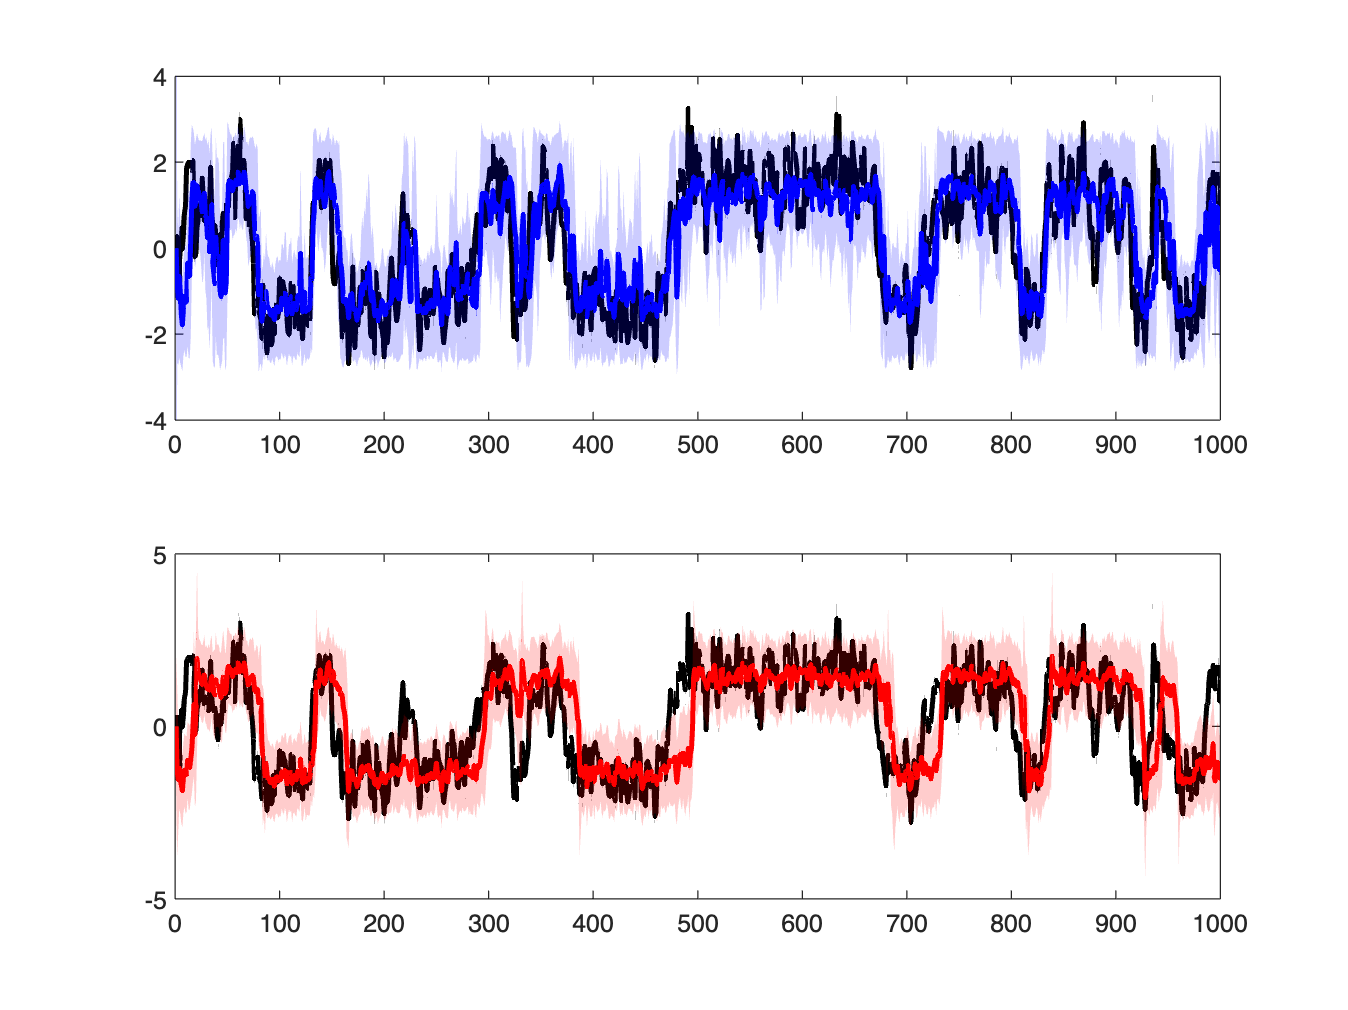

figure; subplot(211); plot(1:N,x,'k',1:N,xN,'b'); U1=xN+2*sqrt(WN); L1=xN-2*sqrt(WN); hold on; fill([1:N N:-1:1], [U1 fliplr(L1)], 'b', 'FaceAlpha',0.2,'EdgeColor','none'); ylim([-4 4])
subplot(212); plot(1:N,x,'k',1:N,xK,'r'); U1=xK+2*sqrt(WK); L1=xK-2*sqrt(WK); hold on; fill([1:N N:-1:1], [U1 fliplr(L1)], 'r', 'FaceAlpha',0.2,'EdgeColor','none'); 

The numerical solution and confidence bounds are shown in the top panel in blue. The EKF estimate and confidence bounds are shown in the bottom panel in red. The true value of x is shown in both panels in black. We see that the EKF estimates the state fairly well, but misses some rapid transitions (around time step 320) and is slower in estimating other transitions (around time step 490).